clear all;
clf reset;

Read data

data = readtable("bananas.csv")

data = 12531×4 table
            Origin               Date       Price     Units  
    ______________________    __________    _____    ________

    {'costa_rica'        }    2022-11-11       1     {'｣/kg'}
    {'guatemala'         }    2022-11-11    0.91     {'｣/kg'}
    {'dollar_bananas'    }    2022-11-11    0.96     {'｣/kg'}
    {'all_bananas'       }    2022-11-11    0.96     {'｣/kg'}
    {'colombia'          }    2022-11-04    0.97     {'｣/kg'}
    {'costa_rica'        }    2022-11-04       1     {'｣/kg'}
    {'dominican_republic'}    2022-11-04     0.9     {'｣/kg'}
    {'acp_bananas'       }    2022-11-04     0.9     {'｣/kg'}
    {'dollar_bananas'    }    2022-11-04       1     {'｣/kg'}
    {'all_bananas'       }    2022-11-04    0.99     {'｣/kg'}
    {'belize'            }    2022-10-28    0.95     {'｣/kg'}
    {'colombia'          }    2022-10-28    0.95     {'｣/kg'}
    {'costa_rica'        }    2022-10-28    0.98     {'｣/kg'}
    {'guatemala'         }    2022-10-28    0.91

Unique Origin and Units

ori = unique(data.Origin);
units = unique(data.Units);

disp("Distinct Origins:")

Distinct Origins:


disp(ori)

    {'acp_bananas'       }
    {'all_bananas'       }
    {'belize'            }
    {'brazil'            }
    {'cameroon'          }
    {'colombia'          }
    {'costa_rica'        }
    {'dollar_bananas'    }
    {'dominican_republic'}
    {'ecuador'           }
    {'eu'                }
    {'eu_bananas'        }
    {'ghana'             }
    {'guadeloupe'        }
    {'guatemala'         }
    {'honduras'          }
    {'ivory_coast'       }
    {'jamaica'           }
    {'malaysia'          }
    {'martinique'        }
    {'mexico'            }
    {'nicaragua'         }
    {'panama'            }
    {'somalia'           }
    {'st_vincent'        }
    {'surinam'           }
    {'venezuela'         }
    {'windward_isles'    }



disp("Count: " + length(ori))

Count: 28


disp("Distinct Units:")

Distinct Units:


disp(units)

    {'｣/kg'}



disp("Count: " + length(units))

Count: 1


There are 28 distinct origins and only 1 unit.

origin_group = grpstats(data, "Origin", "mean", "DataVars", "Price");
mean_prices = origin_group(:, ["mean_Price"])

mean_prices = 28×1 table
                          mean_Price
                          __________

    costa_rica             0.74284  
    guatemala              0.66719  
    dollar_bananas         0.68709  
    all_bananas            0.73941  
    colombia               0.73633  
    dominican_republic     0.63701  
    acp_bananas            0.62421  
    belize                 0.70425  
    panama                 0.76091  
    ivory_coast            0.64778  
    cameroon                0.6698  
    honduras               0.68532  
    ghana                   0.6399  
    ecuador                0.69899  
    guadeloupe             0.56162  
    eu                        0.86  


Group 

n_ori = length(ori);
places = convertCharsToStrings(ori)';

groups = cell(n_ori, 1);

i = 1;
for place = places
    inds = data.Origin == place;
    groups{i} = data(inds, ["Date", "Price"]);
    groups{i} = sortrows(groups{i}, "Date");
    i = i + 1;
end

Plot

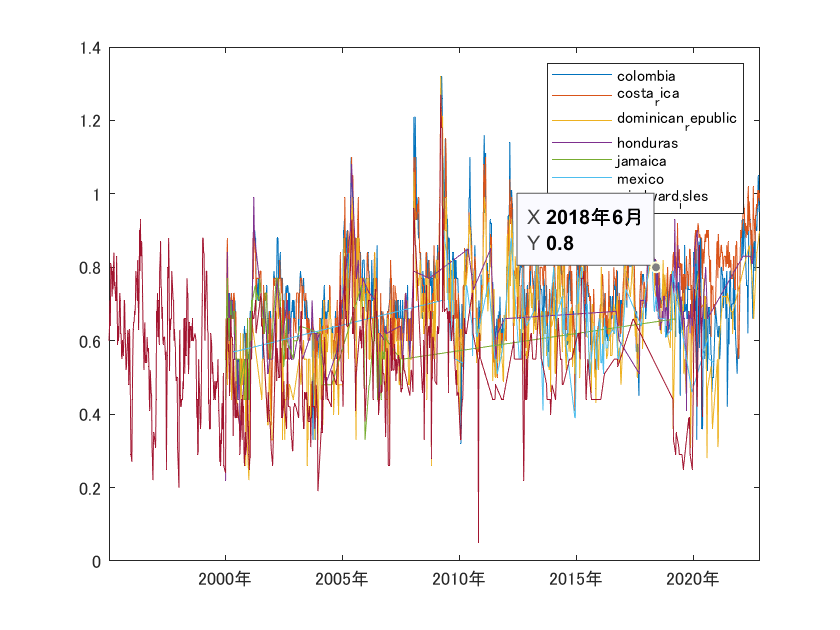

pool = [
    "colombia"
    "costa_rica"
    "dominican_republic"
    "honduras"
    "jamaica"
    "windward_isles"
    "mexico"
];

figure(1);
first = true;
for i = 1 : n_ori
    if sum(pool == places(i)) == 0
        continue;
    end
    context = groups{i};
    ts = table2array(context(:, 1));
    ys = table2array(context(:, 2));
    plot(ts, ys, "DisplayName", places(i));
    if first
        first = false;
        hold on;
    end
    % title(places(i)); 
    % legend()
end
legend();
hold off;

Box Plot

pool = [
    "colombia"
    "costa_rica"
    "dominican_republic"
    "honduras"
    "jamaica"
    "windward_isles"
    "mexico"
];

inpool = @(x) sum(x == pool) > 0;
idxs = [];
for i = 1 : length(data.Origin)
    if sum(inpool(data.Origin(i))) > 0 % the origin is in the array 'pool'
        idxs = [idxs;i];
    end
end

selected = data(idxs, ["Origin", "Price"]) % filter rows with origin in the array

selected = 4081×2 table
            Origin            Price
    ______________________    _____

    {'costa_rica'        }       1 
    {'colombia'          }    0.97 
    {'costa_rica'        }       1 
    {'dominican_republic'}     0.9 
    {'colombia'          }    0.95 
    {'costa_rica'        }    0.98 
    {'colombia'          }    1.02 
    {'costa_rica'        }    1.01 
    {'colombia'          }    1.05 
    {'costa_rica'        }    0.99 
    {'colombia'          }    0.97 
    {'costa_rica'        }    1.01 
    {'colombia'          }    0.96 
    {'costa_rica'        }    0.97 
    {'colombia'          }     0.9 
    {'costa_rica'        }    0.96 


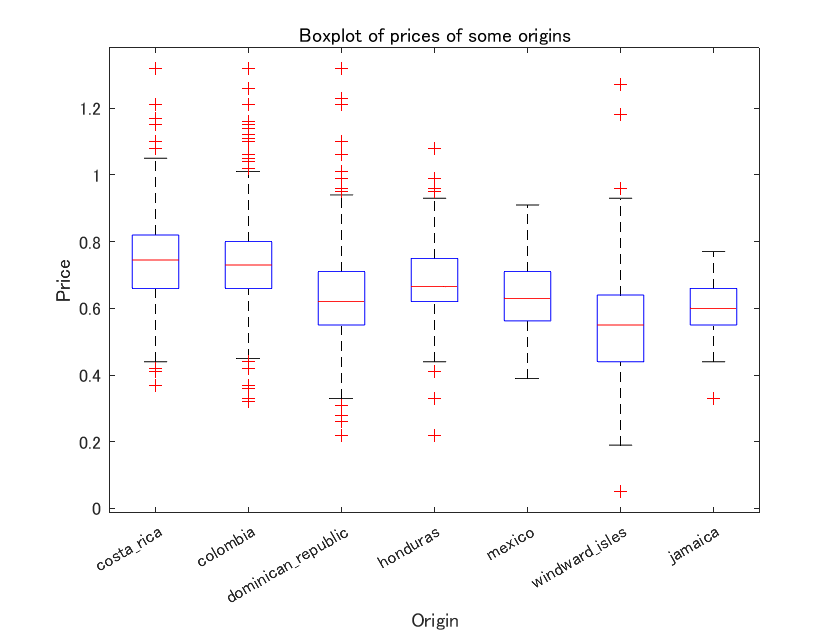

figure;
boxplot(selected.Price, selected.Origin) % plot
title("Boxplot of prices of some origins")
xlabel("Origin")
ylabel("Price")

Time series of colombia

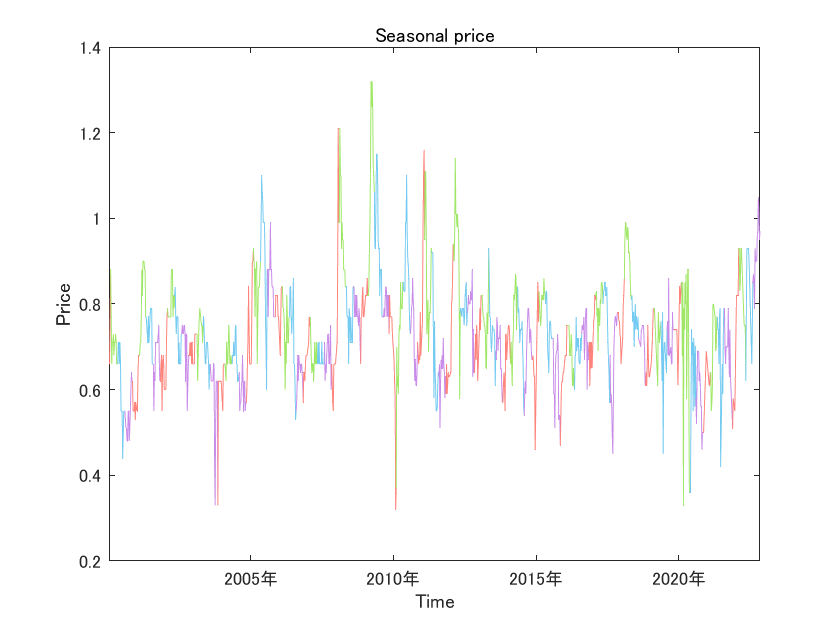

context = groups{6};
ts = table2array(context(:, 1));
ys = table2array(context(:, 2));

colors = [
    [255, 131, 123] / 255;
    [160, 231, 103] / 255;
    [116, 203, 241] / 255;
    [201, 141, 233] / 255;
    [255, 169, 123] / 255;
    [253, 244, 152] / 255
];

figure;
for i = 1 : length(ts) - 1
    t = month(ts(i));
    if t < 2 || t > 10
        c = colors(1, :);
    elseif t < 5
        c = colors(2, :);
    elseif t < 8
        c = colors(3, :);
    else
        c = colors(4, :);
    end
    plot(ts(i:i+1), ys(i:i+1), "Color", c);
    if i == 1
        hold on 
    end
end
title("Seasonal price")
xlabel("Time")
ylabel("Price")
hold off

Correlation

context = groups{7};
ts2 = table2array(context(:, 1));
ys2 = table2array(context(:, 2));

min_time = max(min(datenum(ts)), min(datenum(ts2)));
max_time = min(max(datenum(ts)), max(datenum(ts2)));

int_time = min_time : max_time;
int_time = datetime(int_time, "ConvertFrom", "datenum");

new_ys = interp1(ts, ys, int_time)';
new_ys2 = interp1(ts2, ys2, int_time)';

corrcoef([new_ys new_ys2])

ans =     1.0000    0.7695
    0.7695    1.0000
